# Decoding error as a function of ensemble size, by spatial bin

Loading the precomputed values:

load decoder_by_bins2_agg_210909-141200_0.mat

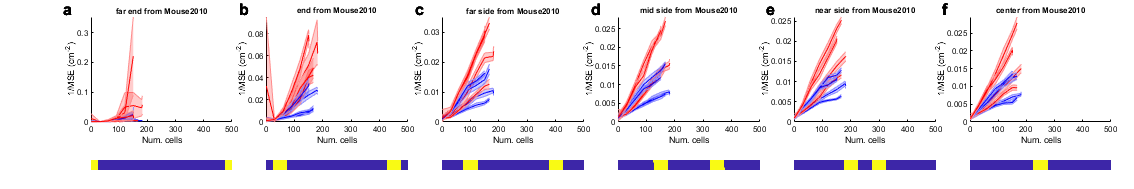

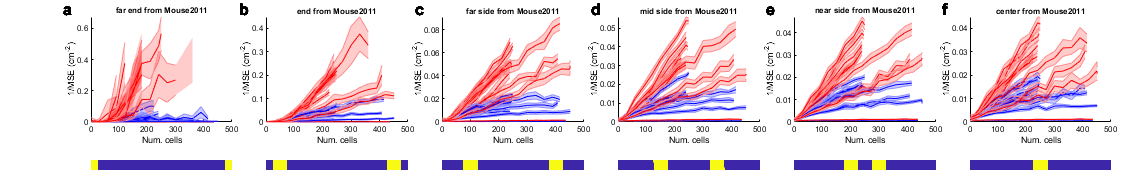

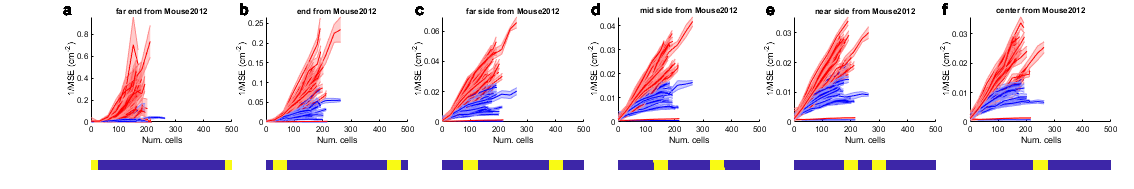

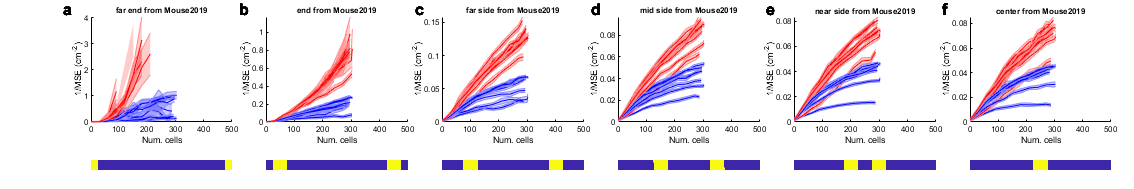

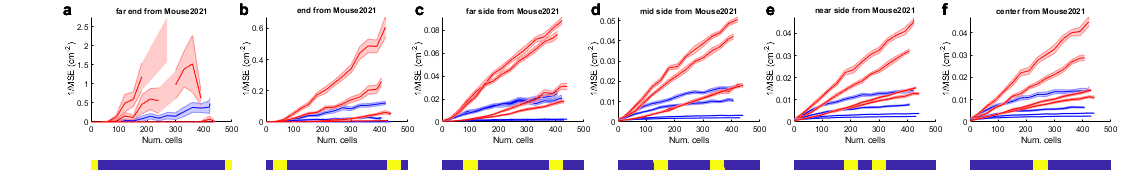

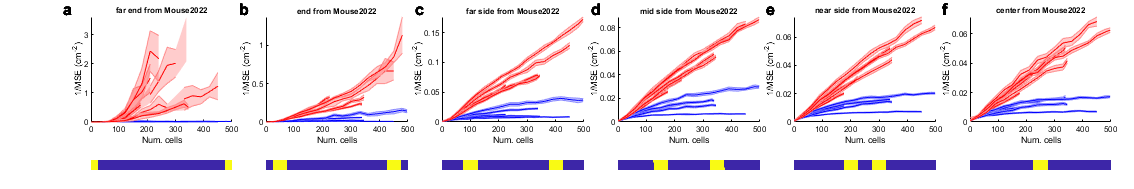

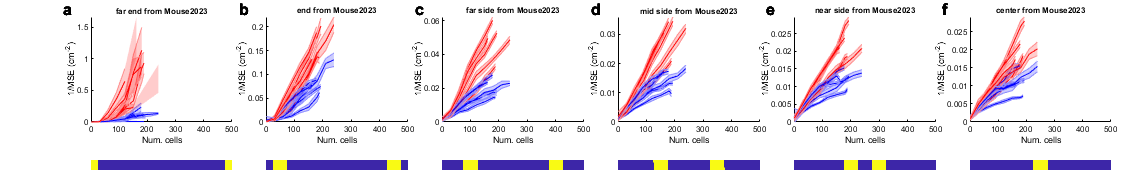

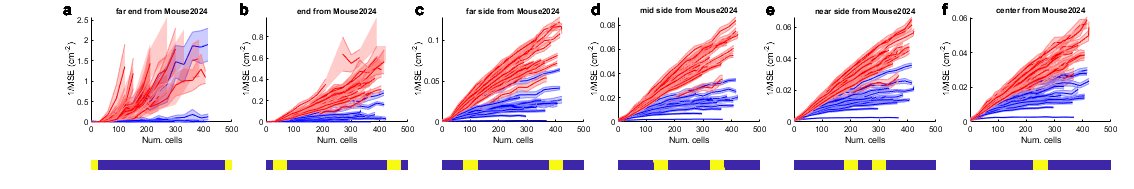

%figure
%tiledlayout(12, 6);

sm = SessManager;
usable_mice = SessManager.usable_mice;

bin_groups = {[1 20], [2 3 18 19], [4 5 16 17], [6 7 14 15], [8 9 12 13], [10 11]};
bg_names = {'far end', 'end', 'far side', 'mid side', 'near side', 'center'};

for m_i = 1:numel(usable_mice)
    my_mouse = usable_mice{m_i};
    using_sess = find(strcmp(my_mouse, {res.mouse_name}));
    using_sess = using_sess(:).';

    %figure;
    %tiledlayout(1,6);
    p = Pub(30,5,'rows',4,'columns',6, 'hspacing', 0.03, 'layout', {{1:3,1},{1:3,2},{1:3,3},{1:3,4},{1:3,5},{1:3,6},{4,1},{4,2},{4,3},{4,4},{4,5},{4,6}});
    for bg_i = 1:numel(bin_groups)
        %nexttile
        %hold on
        bg = bin_groups{bg_i};
        for s_idx = using_sess
            imse_bins = 1 ./ res(s_idx).me_bins.^2;
            imse_bins_shuf = 1./ res(s_idx).me_bins_shuf.^2;
            n_size = res(s_idx).n_size;
            p.panel(bg_i, 'xlab', 'Num. cells',...
                'ylab', '1/MSE (cm^{-2})',...
                'title', sprintf('%s from %s', bg_names{bg_i}, my_mouse),...
                'x_shift', -0.03);
            
            x = squeeze(mean(imse_bins(:, :, bg),3)).';
            x_shuf = squeeze(mean(imse_bins_shuf(:, :, bg),3)).';
            shadedErrorBar(n_size, x, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'b');
            hold on;
            shadedErrorBar(n_size, x_shuf, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'r');
            %title(sprintf('Bin group %d', bg_i));
            ylim([0 Inf]);
            xlim([0 500]);
            xlabel 'Num. cells'
            ylabel '1/MSE (cm^{-2})'
            title(sprintf('%s from %s', bg_names{bg_i}, my_mouse));
            %title(bg_names{bg_i});
            %if bg_i == 1
            %    text(50, 0.2, my_mouse);
            %end
        end
    end
    for bg_i = 1:numel(bin_groups)
        bg = bin_groups{bg_i};
        track_map = ismember(1:20, bg);
        p.panel(bg_i + numel(bin_groups), 'x_shift', -0.03, 'letter', '');
        imagesc(track_map);
        axis off
    end
    %sgtitle(my_mouse);
    p.format;
    Utils.printto(sprintf('events_figs/f2_events/decoding_curves/by_bin/decoding_by_bin_%s.pdf', my_mouse));
end

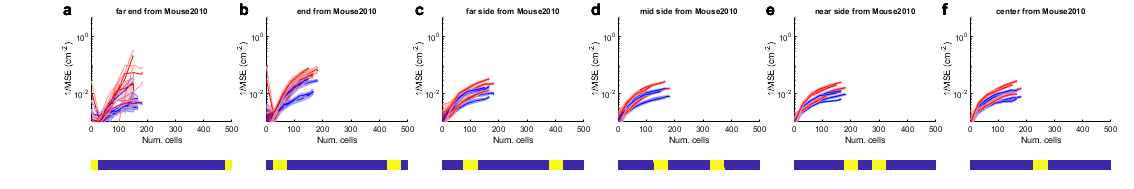

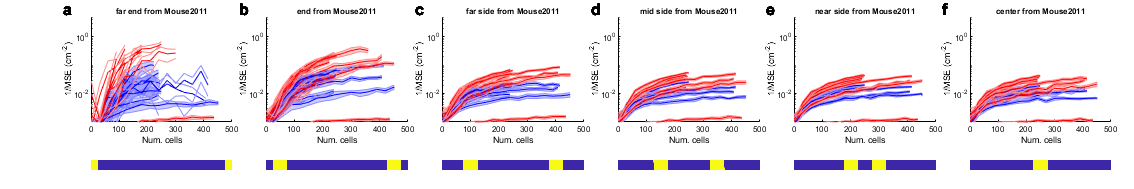

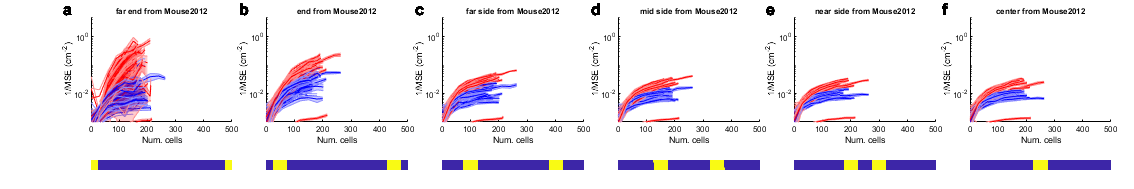

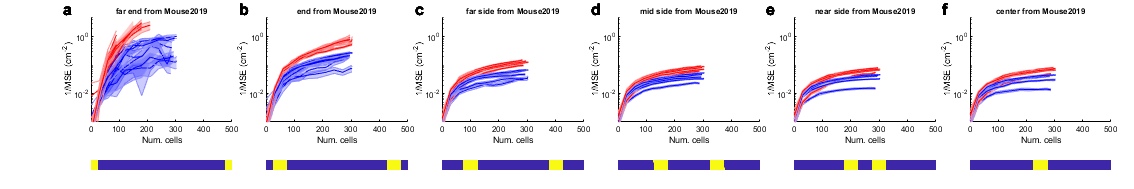

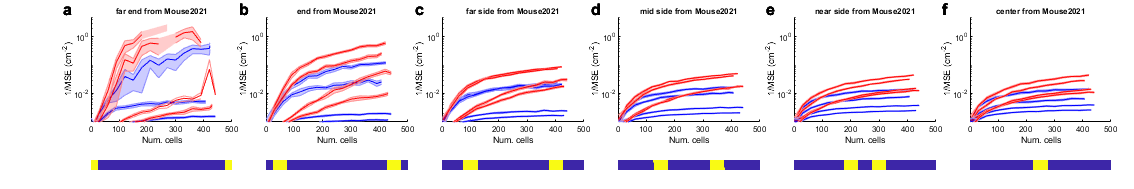

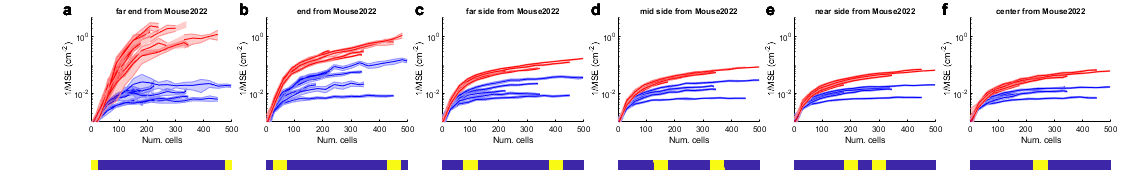

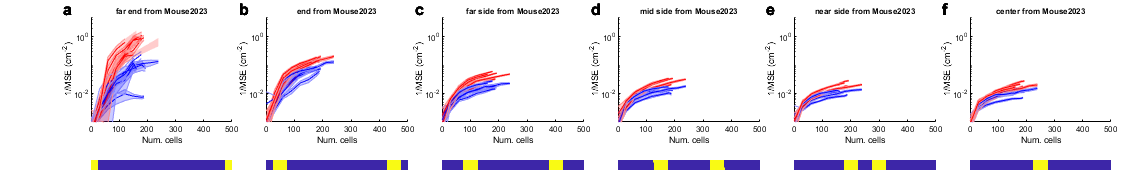

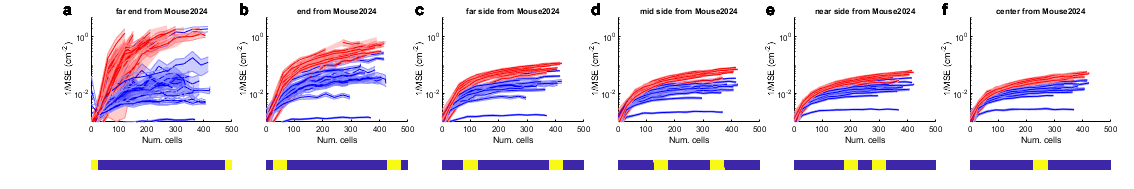

%figure
%tiledlayout(12, 6);

sm = SessManager;
usable_mice = SessManager.usable_mice;

bin_groups = {[1 20], [2 3 18 19], [4 5 16 17], [6 7 14 15], [8 9 12 13], [10 11]};
bg_names = {'far end', 'end', 'far side', 'mid side', 'near side', 'center'};

for m_i = 1:numel(usable_mice)
    my_mouse = usable_mice{m_i};
    using_sess = find(strcmp(my_mouse, {res.mouse_name}));
    using_sess = using_sess(:).';

    %figure;
    %tiledlayout(1,6);
    p = Pub(30,5,'rows',4,'columns',6, 'hspacing', 0.03, 'layout', {{1:3,1},{1:3,2},{1:3,3},{1:3,4},{1:3,5},{1:3,6},{4,1},{4,2},{4,3},{4,4},{4,5},{4,6}});
    for bg_i = 1:numel(bin_groups)
        %nexttile
        %hold on
        bg = bin_groups{bg_i};
        for s_idx = using_sess
            imse_bins = 1 ./ res(s_idx).me_bins.^2;
            imse_bins_shuf = 1./ res(s_idx).me_bins_shuf.^2;
            n_size = res(s_idx).n_size;
            p.panel(bg_i, 'xlab', 'Num. cells',...
                'ylab', '1/MSE (cm^{-2})',...
                'title', sprintf('%s from %s', bg_names{bg_i}, my_mouse),...
                'x_shift', -0.03);
            
            x = squeeze(mean(imse_bins(:, :, bg),3)).';
            x_shuf = squeeze(mean(imse_bins_shuf(:, :, bg),3)).';
            shadedErrorBar(n_size, x, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'b');
            hold on;
            shadedErrorBar(n_size, x_shuf, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'r');
            %title(sprintf('Bin group %d', bg_i));
            ylim([1e-3 5]);
            set(gca, 'YScale', 'log');
            xlim([0 500]);
            xlabel 'Num. cells'
            ylabel '1/MSE (cm^{-2})'
            title(sprintf('%s from %s', bg_names{bg_i}, my_mouse));
            %title(bg_names{bg_i});
            %if bg_i == 1
            %    text(50, 0.2, my_mouse);
            %end
        end
    end
    for bg_i = 1:numel(bin_groups)
        bg = bin_groups{bg_i};
        track_map = ismember(1:20, bg);
        p.panel(bg_i + numel(bin_groups), 'x_shift', -0.03, 'letter', '');
        imagesc(track_map);
        axis off
    end
    %sgtitle(my_mouse);
    p.format;
    Utils.printto(sprintf('events_figs/f2_events/decoding_curves/by_bin_log/decoding_by_bin_%s_logscale.pdf', my_mouse));
end

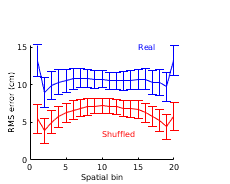

m = squeeze(mean(cat(3, res.me_bins_max), 1)).';
m_s = squeeze(mean(cat(3, res.me_bins_shuf_max), 1)).';
n_sess = size(m, 1);

figure;
errorbar(1:20, mean(m), 1.96*std(m)./sqrt(n_sess), 'b');
hold on;
errorbar(1:20, mean(m_s), 1.96*std(m_s)./sqrt(n_sess), 'r');
xlabel 'Spatial bin'
ylabel 'RMS error (cm)'

text(15, 15, 'Real', 'Color', 'b');
text(10, 3.5, 'Shuffled', 'Color', 'r');

figure_format([1.5 1.2]);
Utils.printto('events_figs/f2_supplements', 'decoding_error_by_bins.pdf');